Xuetong Du SID: 9078172542 UW Login: xdu49

% 1a
% read the image in
pic1 = double(imread('~/MatlabProjects/cs567hw1/img_001.ppm'));

% 605 is the height (row), 700 is its width(column) and 3 represents 
% the three channels: red green and blue
[h,w,d]=size(pic1);
disp([h,w,d]);

   605   700     3




meanpic1 = mean(pic1,3);
% this gives the lowest intensity: 4
low_intensity = min(meanpic1(:));
disp(low_intensity);

     4




% this gives the highest intensity: 193.33
high_intensity = max(meanpic1(:));
disp(high_intensity);

  193.3333




% total pixels is height * weight = 423500
disp(h * w);

      423500



%1b
% when not reading in double, the detail information were lost after 
% division due to the result only round to integer. Changing the image 
% to double precision can solve the problem.

disp(pic1(1,1,1)/3)

    3.6667



disp(pic1(2,1,1)/3)

    3.3333



disp(pic1(3,1,1)/3);

     3



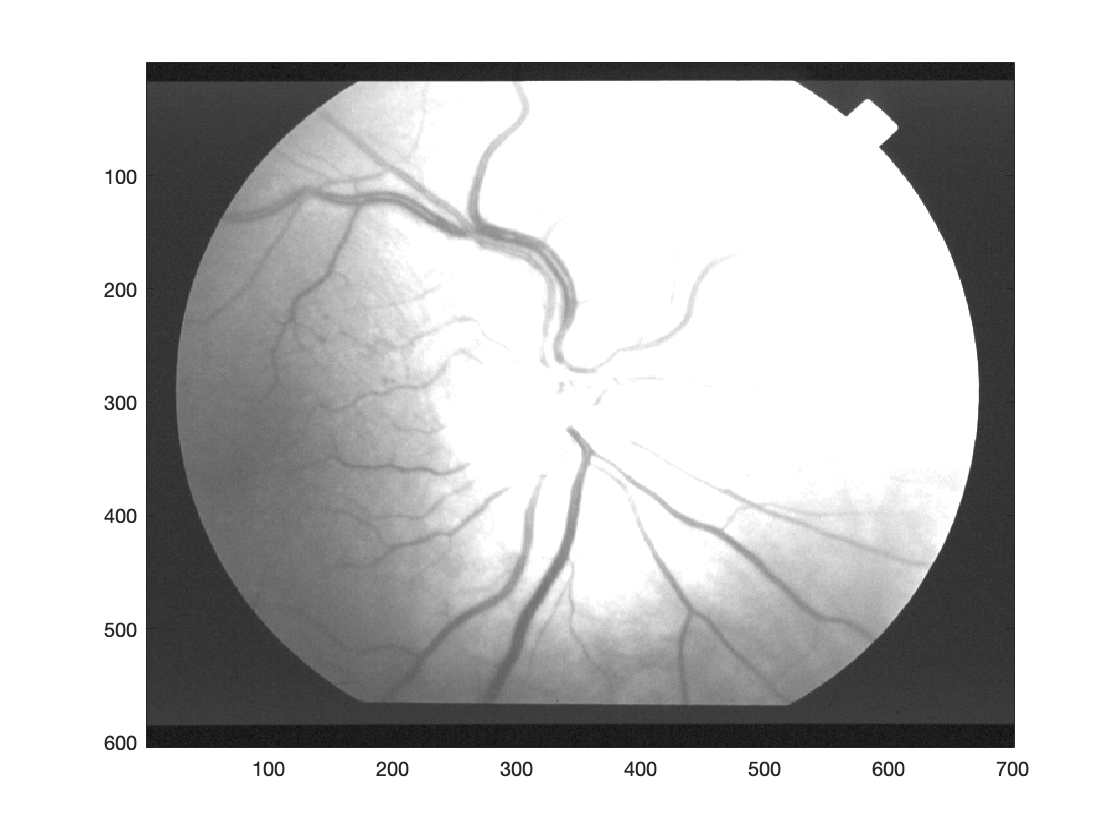

% 1c
% image() displays the imput array as an image without automatically
% scaling
% imagesc() is the same as image() except the data is scaled to use 
% the full colormap.
% When displaying the green channel of the image in gray using image and
% imagesc, they outputs looks quite different as the output from imagesc
% has been scaled
green = pic1(:,:,2);
figure, image(green)
colormap(gray);

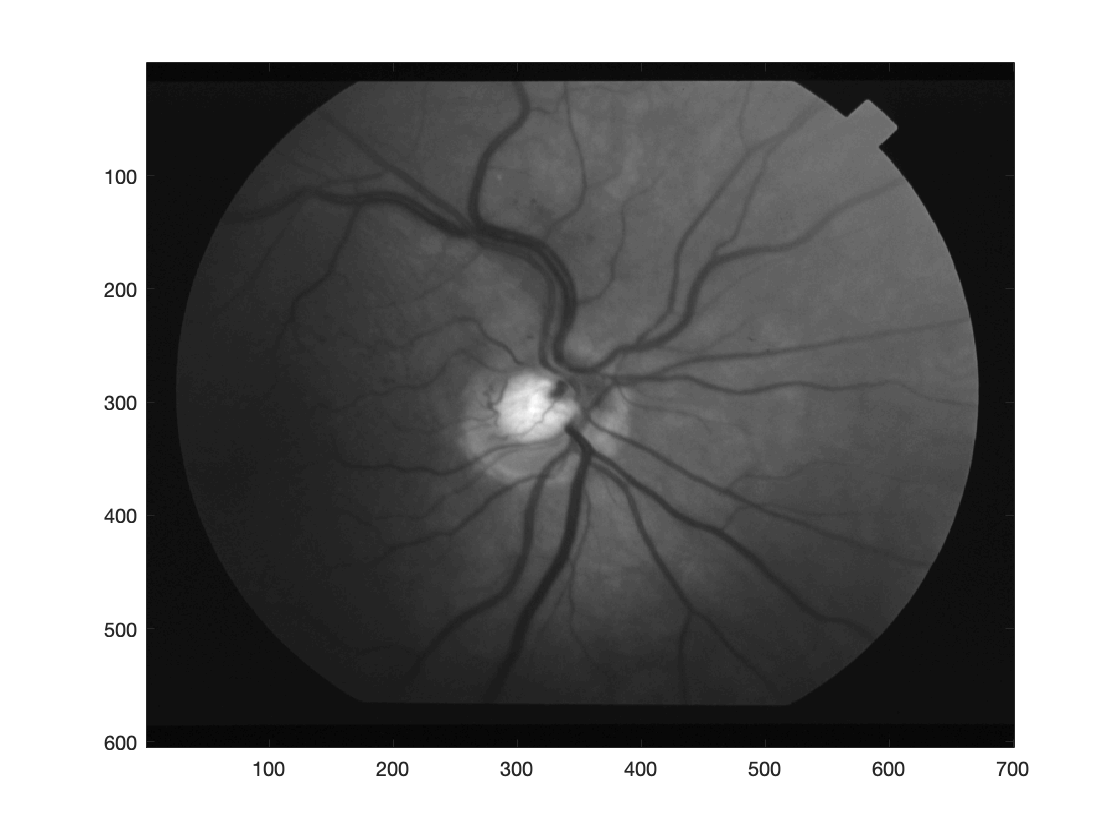

figure, imagesc(green)
colormap(gray);

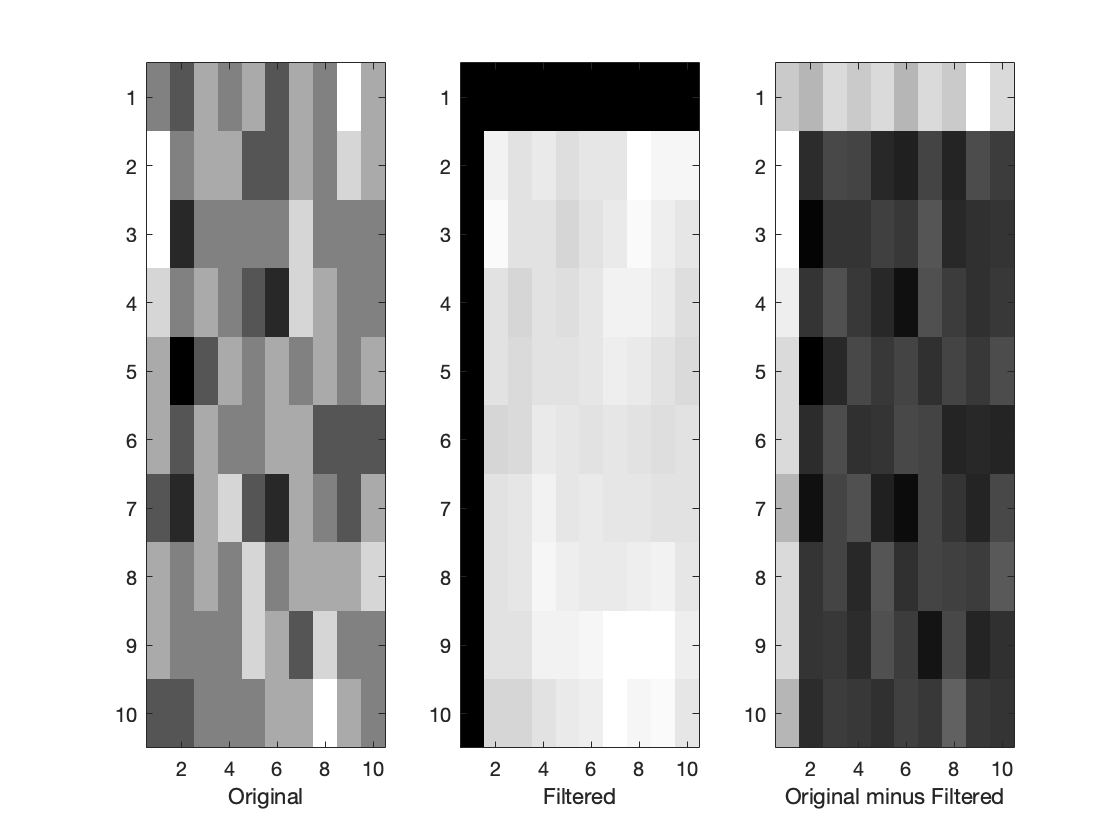

% 2a
% Use only for loop and mean, Filter the image and print out the values 
% for the 100 pixels in the first 101 columns and rows.  Also make a 1×3 
% panel plot where the left panel 
% is the original image themiddle panel is the filtered image and the right 
% panel is the original minus the filtered.  Labelthe images, accordingly. 
green = pic1(:,:,2);
dblarray = double(green);
img_filt = zeros(605,700);
for x = 2:604
    for y = 2:699
        p = reshape(dblarray(x-1:x+1,y-1:y+1),9,1);
        img_filt(x,y) = mean(p);
    end
end
figure;
img_filt(1:10,1:10);
colormap('gray');
subplot(1,3,1);
imagesc(dblarray(1:10,1:10));
xlabel('Original')
subplot(1,3,2);
imagesc(img_filt(1:10,1:10));
xlabel('Filtered')
subplot(1,3,3);
imagesc(green(1:10,1:10)-img_filt(1:10,1:10));
xlabel('Original minus Filtered');

2b

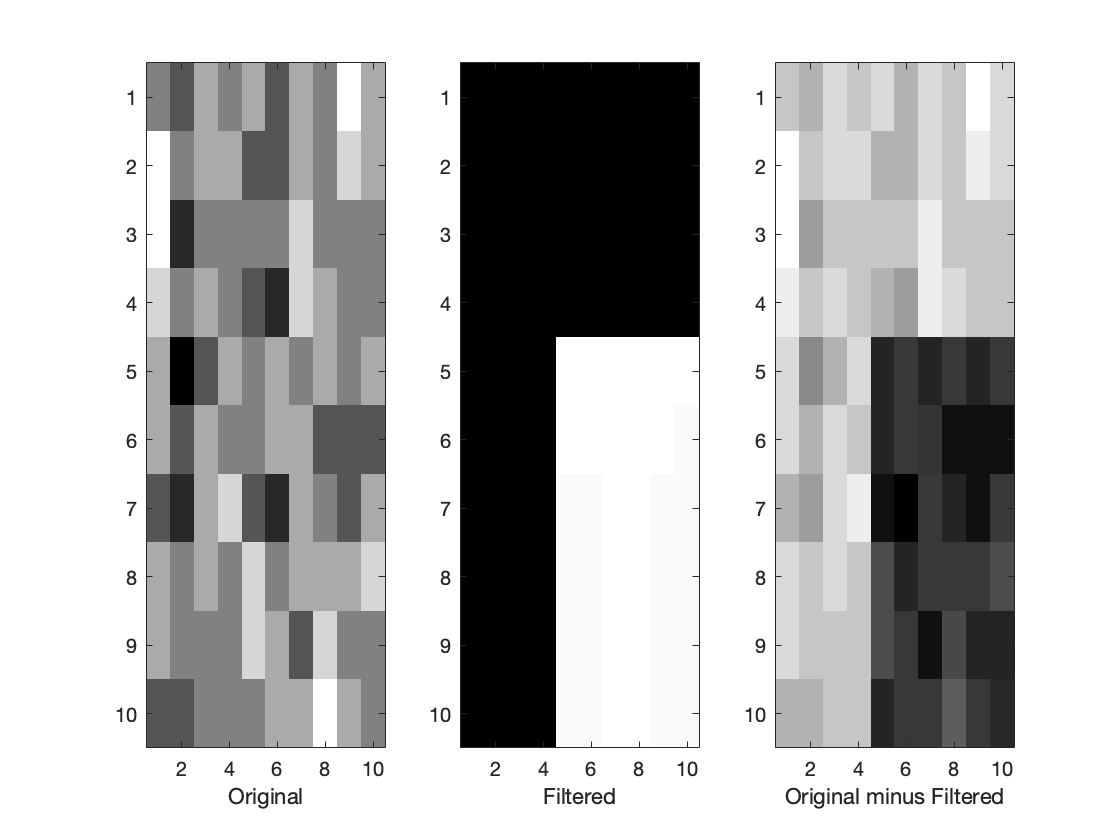

green = pic1(:,:,2);
dblarray = double(green);
img_filt = zeros(605,700);
for x = 5:600
    for y = 5:695
        p = reshape(dblarray(x-4:x+4,y-4:y+4),81,1);
        img_filt(x,y) = mean(p);
    end
end

crop = img_filt(1:10,1:10);
figure
colormap('gray');
subplot(1,3,1);
imagesc(dblarray(1:10,1:10));
xlabel('Original')
subplot(1,3,2);
imagesc(crop);
xlabel('Filtered')
subplot(1,3,3);
imagesc(green(1:10,1:10)-img_filt(1:10,1:10));
xlabel('Original minus Filtered');

% 2c
% The artifact in the original image but dissppears after the subtraction
% is the pixels that are either too dark or too bright in the areas which 
% are supposed to be light/dark oppositely
%
% The artifact which has been introduced could be the boundary between the 
% brighter pixels and darker pixels which seperates the image to 2 parts

3

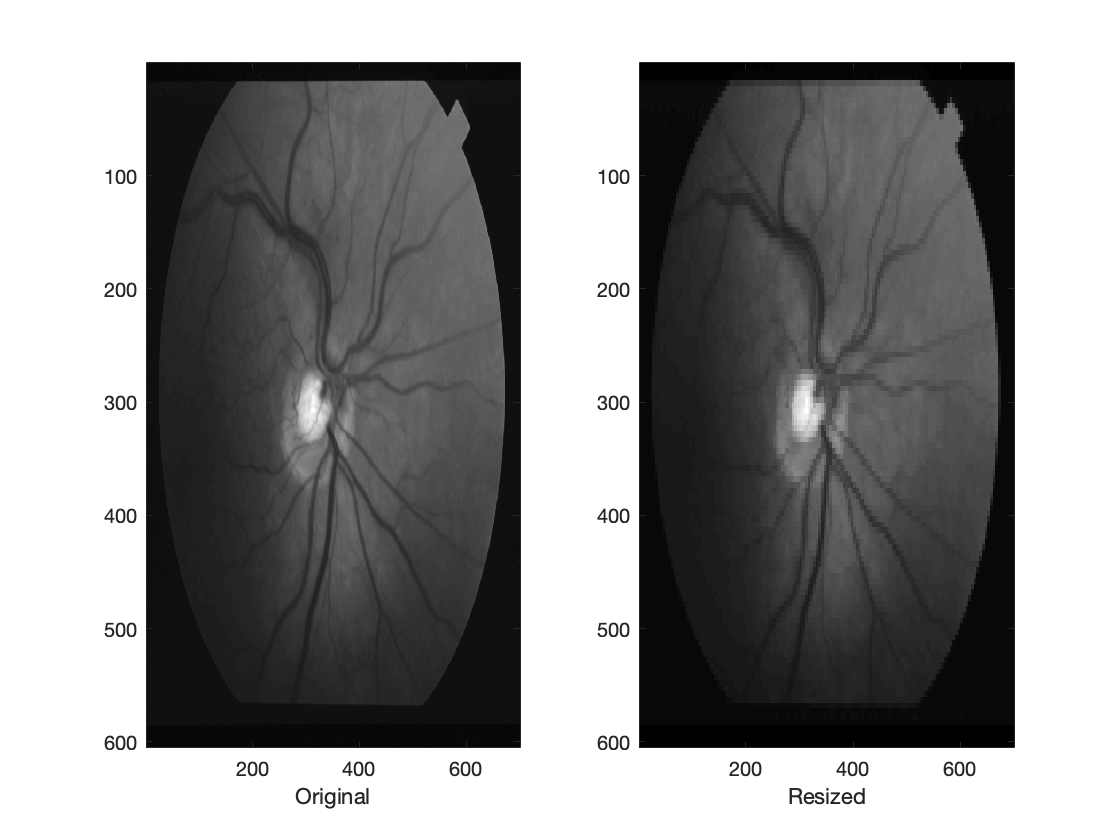

green = pic1(:,:,2);
dblarr = double(green);
new_image = zeros(605,700);
for x = 1:5:601
    for y = 1:5:696
        p = reshape(dblarr(x:x+4,y:y+4),25,1);
        new_image(x:x+4,y:y+4) = mean(p)*ones(5);
    end
end

figure;
colormap('gray');
subplot(1,2,1);
imagesc(dblarr);
xlabel('Original')
subplot(1,2,2);
imagesc(new_image);
xlabel('Resized')